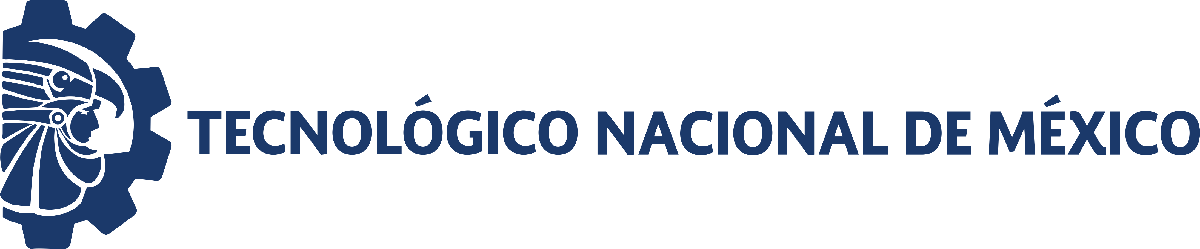                                 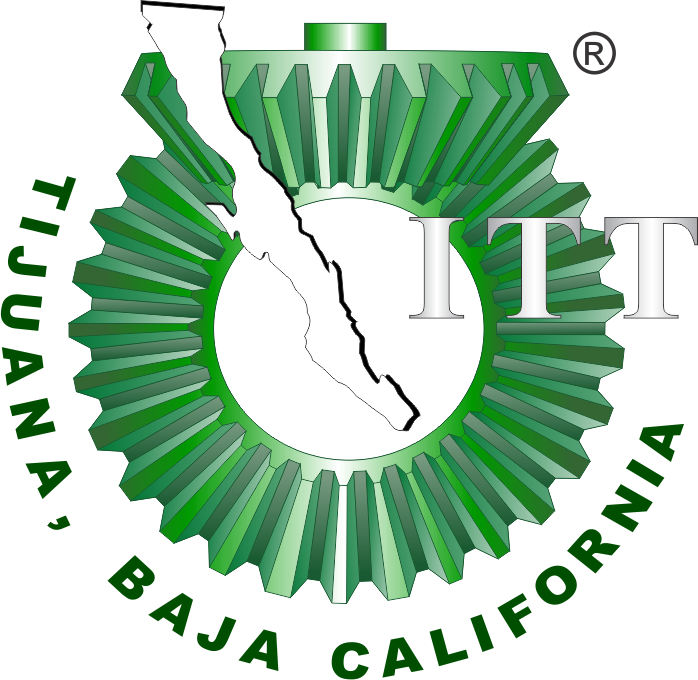

# Práctica 5: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Maria Belen Galindo Ramirez                                                                 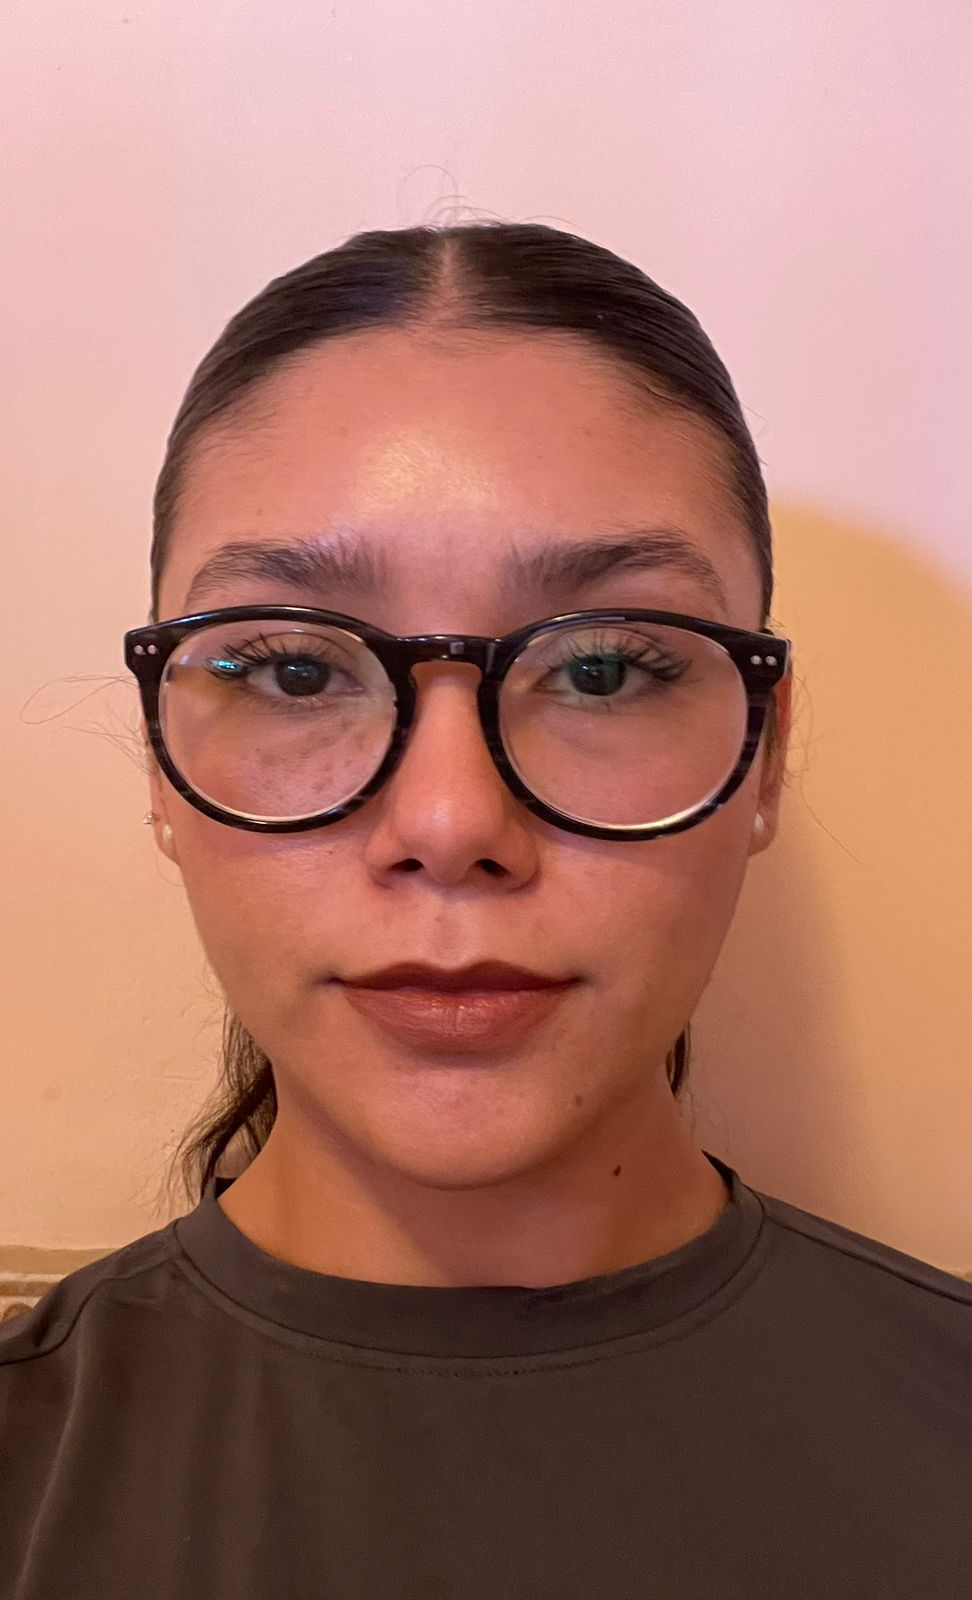

Número de control: 22211755

Correo institucional: l22211755**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación: Lazo Abierto

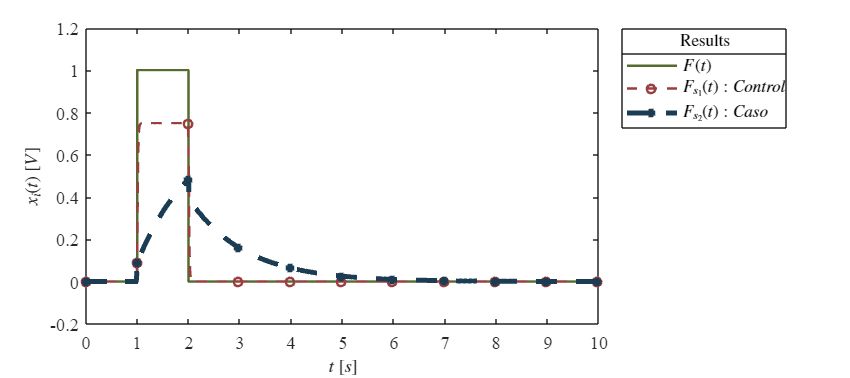

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);
plotsignals(x.t,x.F,x.Fs1,x.Fs2,'grafica')

## Lazo Cerrado 

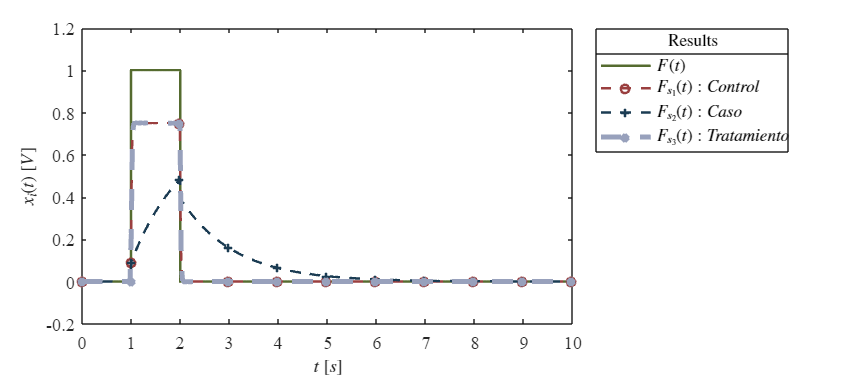

x2 = sim(file,parameters);
plotsignals2(x2.t,x2.F,x2.Fs1,x2.Fs2,x2.Fs3,'grafica')

## Función 1 

function plotsignals(t,F,Fs1,Fs2,Signal)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [85,107,47;
            154,63,63;
            27,60,83;
            152,161,188;
            51,56,160;
            249,122,0]/255;
colororder(mycolors)

p =  plot(t,F,'-',t,Fs1,'--O',t,Fs2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(3),'LineWidth',3);
 L = legend('$F(t)$','$F_{s_1}(t): Control$','$F_{s_2}(t): Caso$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Results','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

 xlim([0,10]);xticks(0:1:10);
 ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);



 exportgraphics(gcf,[Signal,'_lazoAbierto.pdf'], 'ContentType','vector')
 exportgraphics(gcf,[Signal,'_lazoAbierto.png'], 'Resolution',300)

end



## Función 2 


function plotsignals2(t,F,Fs1,Fs2,Fs3,Signal)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [85,107,47;
            154,63,63;
            27,60,83;
            152,161,188;
            51,56,160;
            249,122,0]/255;
colororder(mycolors)

p =  plot(t,F,'-',t,Fs1,'--O',t,Fs2,'--+',t,Fs3,'--x',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(4),'LineWidth',3);
 L = legend('$F(t)$','$F_{s_1}(t): Control$','$F_{s_2}(t): Caso$','$F_{s_3}(t): Tratamiento$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Results','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

 xlim([0,10]);xticks(0:1:10);
 ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);

 exportgraphics(gcf,[Signal,'_lazoCerrado.pdf'], 'ContentType','vector')
 exportgraphics(gcf,[Signal,'_lazoCerrado.png'], 'Resolution',300)

end
